# Import data from text file

clear
close all

## SIMULATION FOLDER LIST: 

% Put your folder list here
simu_list = ["/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_simu/rosbag2_2023_05_31-18_35_46/rosbag2_2023_05_31-18_35_46_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_simu/rosbag2_2023_05_31-18_28_36/rosbag2_2023_05_31-18_28_36_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_simu/rosbag2_2023_05_31-18_28_20/rosbag2_2023_05_31-18_28_20_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_simu/rosbag2_2023_05_31-18_27_54/rosbag2_2023_05_31-18_27_54_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_simu/rosbag2_2023_05_31-18_27_24/rosbag2_2023_05_31-18_27_24_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_simu/rosbag2_2023_05_31-18_24_27/rosbag2_2023_05_31-18_24_27_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_simu/rosbag2_2023_05_31-18_22_55/rosbag2_2023_05_31-18_22_55_"];

## EXPERIMENT FOLDER LIST

% Put your folder list here
exp_list = ["/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_drone/0/rosbag2_2023_05_31-19_45_25/rosbag2_2023_05_31-19_45_25_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_drone/x/0.1/rosbag2_2023_05_31-19_46_30/rosbag2_2023_05_31-19_46_30_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_drone/x/0.1/rosbag2_2023_05_31-19_46_54/rosbag2_2023_05_31-19_46_54_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_drone/x/0.2/rosbag2_2023_05_31-19_47_40/rosbag2_2023_05_31-19_47_40_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_drone/x/0.2/rosbag2_2023_05_31-19_47_56/rosbag2_2023_05_31-19_47_56_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_drone/x et y/rosbag2_2023_05_31-19_52_13/rosbag2_2023_05_31-19_52_13_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_drone/x et y/rosbag2_2023_05_31-19_53_17/rosbag2_2023_05_31-19_53_17_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_drone/y/rosbag2_2023_05_31-19_51_50/rosbag2_2023_05_31-19_51_50_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_drone/rosbag2_2023_05_30-13_10_53/rosbag2_2023_05_30-13_10_53_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_drone/rosbag2_2023_05_31-19_14_03/rosbag2_2023_05_31-19_14_03_",
    "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_drone/rosbag2_2023_05_31-19_17_50/rosbag2_2023_05_31-19_17_50_"];

% Choose your folder list here
folder_list = exp_list;

% Choose the experiment to analyse
i=9

i = 9

folder = folder_list(i)

folder = "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_drone/rosbag2_2023_05_30-13_10_53/rosbag2_2023_05_30-13_10_53_"

% LOAD data
[ref,control,simu_state,optitrack] = load_all_data(folder,false); % true or false to see tables
% PLOT position
% Simulation results :
%plot_x_y_theta(ref,simu_state,"simulation",[0.5,0.5,1]) % Last array is used to plot the bounds
% Experiment results :
plot_x_y_theta(ref,optitrack,"Optitrack",[0.5,0.5,1]) % Last array is used to plot the bounds

% PARAMETRIC plot position : 
% Simulation results :
%plot_parametric_position(ref,simu_state,"simulation")
% Experiment results :
plot_parametric_position(ref,optitrack,"Simulation")

% PLOT velocities
plot_vx_vy_wz(ref,simu_state,"Simulation",[0.5,0.5,1])


%% PLOT control
plot_control(control,0.2); % Second value is used to plot maximum control signal

## PLOTTING LOOP

     1



folder = "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_drone/0/rosbag2_2023_05_31-19_45_25/rosbag2_2023_05_31-19_45_25_"

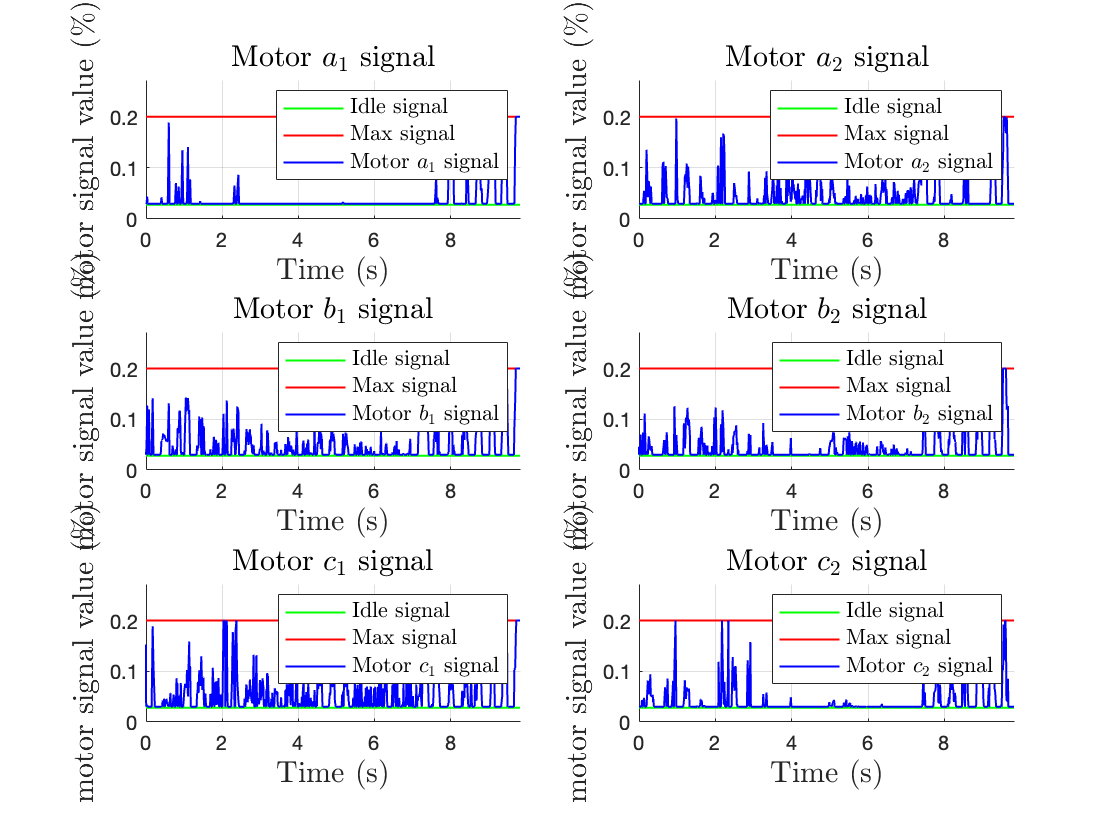

     2



folder = "/Users/Etienne/Documents/EPFL_class/Semester project 1/holohover_20230531_drone/x/0.1/rosbag2_2023_05_31-19_46_30/rosbag2_2023_05_31-19_46_30_"

Error using matlab.graphics.axis.Axes/set
Value must be a 1x2 vector of numeric type in which the second element is greater than the first element or is Inf.

Error in axis>LocSetLimits (line 291)
    set(ax,...

Error in axis (line 113)
                LocSetLimits(ax(j),cur_arg,nam

% To plot the old folder :
for i=1:11
    disp(i)
    folder = folder_list(i)
    % LOAD
    [ref,control,simu_state,optitrack] = load_all_data(folder,false); % true or false to see tables
    % PLOT position
    %plot_x_y_theta(ref,simu_state,"Simulation",[0.3,0.3,3])
    plot_x_y_theta(ref,optitrack,"Optitrack")
    % PLOT parametric position
    %plot_parametric_position(ref,simu_state,"simulation")
    plot_parametric_position(ref,optitrack,"Optitrack")
    % PLOT velocities
    plot_vx_vy_wz(ref,simu_state,"Simulation",[0.5,0.5,0.5])

    %PLOT control
    plot_control(control,0.2);

end

## Clear temporary variables

clear opts